clear all;

% Make sure startup is updated with personal path to ToolboxToolbox before
% running rest of code and check output of tbUseProject for any errors.
startup

Resetting path to factory state.
Adding "ToolboxToolbox" to path at "/mnt/DataDrive3/emeyer/MATLAB/ToolboxToolbox".


tbUseProject('ISETTreeShrew');

Locating project "ISETTreeShrew" within "/mnt/DataDrive3/emeyer/MATLAB/projects".
  Found at "/mnt/DataDrive3/emeyer/MATLAB/projects/ISETTreeShrew".
Local copy of ToolboxToolbox is up to date.
Updating "ToolboxRegistry".
Already up to date.
Updating "ISETTreeShrew".
Already up to date.
Updating "isetbio".
Your configuration specifies to merge with the ref 'refs/heads/master'
from the remote, but no such ref was fetched.
Updating "UnitTestToolbox".
Already up to date.
Updating "RemoteDataToolbox".
Already up to date.
Updating "ExampleTestToolbox".
Already up to date.
Found "jsonlab_v1.2" and skipping update.
Updating "ISETPipelineToolbox".
Already up to date.
Found "Palamedes_1.8.2" and skipping update.
Resetting path to factory state.
Adding "ToolboxToolbox" to path at "/mnt/DataDrive3/emeyer/MATLAB/ToolboxToolbox".
Adding "ISETTreeShrew" to path at "/mnt/DataDrive3/emeyer/MATLAB/projects/ISETTreeShrew/toolbox".
Adding "ISETTreeShrew" to path at "/mnt/DataDrive3/emeyer/MATLAB/projects/

% Specify location for storing cone mosaics and render matrices. Render
% matrices can be quite large so make sure space is available.
dataSavePath = '/mnt/DataDrive2/treeshrew/data_raw/treeshrew_isetbio/';

% Specify parameters for full cone mosaic and render matrix located at a
% specific location in visual space.
species = 'treeshrew';
imOrigSize = 20;
sceneFOVdegs = 0.25;
sceneFOVpadding = 1.2;
eccX = 0;
eccY = 0;
retina = ConeResponseCmosaic(eccX,eccY,'fovealDegree',sceneFOVdegs*sceneFOVpadding);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 20 workers.
Override, will not create mosaic and optics object 
Loading cone mosaic data from /mnt/DataDrive3/emeyer/MATLAB/toolboxes/isetbio/isettools/ganglioncells/data/lattices/right_eye_cones_58deg_mosaic.


% Set mosaic size params
mosaicFOVdegs = [sceneFOVdegs*sceneFOVpadding sceneFOVdegs*sceneFOVpadding];

% Integration time
integrationTimeSeconds = 1/1000;

% Set mean luminance
meanLuminanceCdPerM2 = 20;

% Set string for save paths
FOV_str = num2str(sceneFOVdegs);

if strcmp(species,'human')
    % Generate human optical image
    HumanOI = oiCreate('wvf human');

    % Load or create cone mosaic
    try
        load([dataSavePath,'coneMosaics_test/human/coneMosaic_deg',FOV_str,'.mat'],'HumanConeMosaic')
    catch
        HumanConeMosaic = cMosaic('sizeDegs',mosaicFOVdegs,'eccentricityDegs',[eccX,eccY]);
        save([dataSavePath,'/coneMosaics_test/human/coneMosaic_deg',FOV_str,'.mat'],'HumanConeMosaic')
    end

    % Enter mosaic and OI into retina object. Could also specify display
    % params as retina.Display but defaults are used here.
    retina.Mosaic = HumanConeMosaic;
    retina.PSF = HumanOI;

elseif strcmp(species,'treeshrew')
    % Generate tree shrew optical image
    TSOI = oiTreeShrewCreate('opticsType','wvf','name','wvf-based optics');

    % Load or create cone mosaic
    try
        load([dataSavePath,'/coneMosaics_test/treeshrew/coneMosaic_deg',FOV_str,'.mat'],'TSConeMosaic')
    catch
        TSConeMosaic = cMosaicTreeShrewCreate('fovDegs', mosaicFOVdegs,'integrationTime', integrationTimeSeconds,'eccentricityDegs',[eccX,eccY]);
        save([dataSavePath,'/coneMosaics_test/treeshrew/coneMosaic_deg',FOV_str,'.mat'],'TSConeMosaic')
    end

    % Enter mosaic and OI into retina object. Could also specify display
    % params as retina.Display but defaults are used here.
    retina.Mosaic = TSConeMosaic;
    retina.PSF = TSOI;
end


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 8
Scones after making an S-cone free central patch: 8 (added Lcones:0, added Mcones:0)
Scones after pass 1: 5 (added Lcones:5, added Mcones:0)
Scones after pass 2: 3 (added Lcones:3, added Mcones:0)
Scones after pass 3: 2 (added Lcones:2, added Mcones:0)
Scones after pass 4: 2 (added Lcones:0, added Mcones:0)
Achieved cone densities: L (0.882), M (0.000), S (0.118), K (0.000)


% Generate test image based on block size
imageSize = [round(imOrigSize*sceneFOVpadding), round(imOrigSize*sceneFOVpadding), 3];
testImage = rand(imageSize);

% Compute cone excitations in response to test image
[coneExcitations, linearStimulusImage] = retina.compute(testImage);

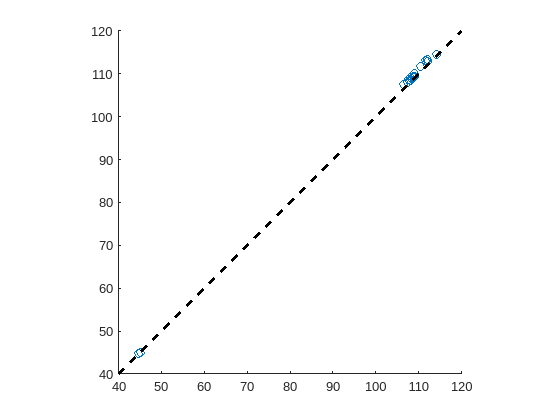

% Compute render matrix. May take a long time depending on size of image!
% I have updated some parallel processing allocations within
% ConeResponseCmosaic script.
renderMtx = retina.forwardRender(imageSize, true, true, 'useDoublePrecision', true);

renderMtx = double(renderMtx);
save([dataSavePath,'renderMatrices_test/',species,'/render_',FOV_str,'.mat'],'renderMtx','-v7.3')

Error using horzcat
Dimensions of arrays being concatenated are not consistent.